## Bounding Boxes - Long Thing 

Correct Objects 

LTCorrect = detectImportOptions("C:\Users\fduro\Documents\SDU\Bachelor\Bachelor_Lego\TestData\Long Thing\Correct\Correct2\BB-Correct.csv")

LTCorrect =   DelimitedTextImportOptions with properties:

   Format Properties:
                    Delimiter: {','}
                   Whitespace: '\b\t '
                   LineEnding: {'\n'  '\r'  '\r\n'}
                 CommentStyle: {}
    ConsecutiveDelimitersRule: 'split'
        LeadingDelimitersRule: 'keep'
       TrailingDelimitersRule: 'ignore'
                EmptyLineRule: 'skip'
                     Encoding: 'UTF-8'

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'
             ExtraColumnsRule: 'addvars'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'LapNr', 'Roi1', 'Roi1_x' ... and 3 more}
                VariableTypes: {'double', 'char', 'double' ... and 3 more}
        SelectedVari

LTCorrect.SelectedVariableNames = {'Roi1_x','Roi1_y','Roi1_w','Roi1_h'};
Correct = readtable('C:\Users\fduro\Documents\SDU\Bachelor\Bachelor_Lego\TestData\Long Thing\Correct\Correct2\BB-Correct.csv', LTCorrect);
Correct(1:50,:)

ans = 50×4 table
    Roi1_x    Roi1_y    Roi1_w    Roi1_h
    ______    ______    ______    ______

      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  
      0         6        411        23  


#### Cut Object

LTcut = detectImportOptions("C:\Users\fduro\Documents\SDU\Bachelor\Bachelor_Lego\TestData\Long Thing\Malfunction\Correct2\BB-cut.csv");
LTcut.SelectedVariableNames = {'Roi1_x','Roi1_y','Roi1_w','Roi1_h'};
cut = readtable('C:\Users\fduro\Documents\SDU\Bachelor\Bachelor_Lego\TestData\Long Thing\Malfunction\Correct2\BB-cut.csv',LTcut);
cut(1:4,:)

ans = 4×4 table
    Roi1_x    Roi1_y    Roi1_w    Roi1_h
    ______    ______    ______    ______

     220        1        189        27  
     220        1        189        27  
     220        1        189        27  
     220        1        189        27  


#### Streched Object

LTstretched = detectImportOptions("C:\Users\fduro\Documents\SDU\Bachelor\Bachelor_Lego\TestData\Long Thing\Strected out\BB-stretched.csv");
LTstretched.SelectedVariableNames = {'Roi1_x','Roi1_y','Roi1_w','Roi1_h'};
stretched = readtable('C:\Users\fduro\Documents\SDU\Bachelor\Bachelor_Lego\TestData\Long Thing\Strected out\BB-stretched.csv',LTstretched);
stretched(1:5,:)

ans = 5×4 table
    Roi1_x    Roi1_y    Roi1_w    Roi1_h
    ______    ______    ______    ______

     270        0        131        83  
     273        0        128        83  
     267        0        134        83  
     273        0        128        83  
     270        0        131        83  


### Histograms

#### All Data 

Width

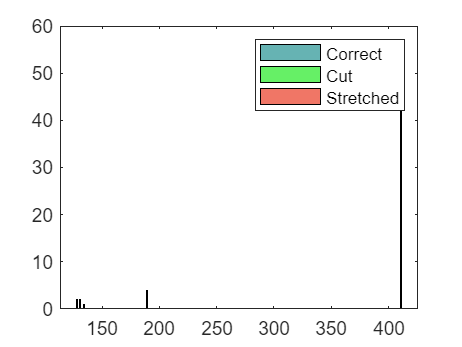

Hist_Wcorrect =histogram(Correct.Roi1_w,FaceColor = [0 0.5 0.5]);
hold on
Hist_Wcut =histogram(cut.Roi1_w,FaceColor = [0 0.9 0]);
Hist_Wstretched = histogram(stretched.Roi1_w,FaceColor = [0.9 0.1 0]);
%Hist_WM =histogram(wMal,FaceColor = [0.5 0.1 0.5]);
legend('Correct','Cut','Stretched')

Height

% Hist_Hcorrect =histogram(Correct.Roi1_h,FaceColor = [0 0.5 0.5]);
% hold on
% Hist_Hcut =histogram(cut.Roi1_h,FaceColor = [0 0.9 0]);
% Hist_Hstretched = histogram(stretched.Roi1_h,FaceColor = [0.9 0.1 0]);
% %Hist_WM =histogram(wMal,FaceColor = [0.5 0.1 0.5]);
% legend('Correct','Cut','Stretched')